clear
syms x y
assume(x, {'real'})
assume(y, {'real'})

f = x * y - x^2 - y^2 - 2*x - 2*y - 4

$$f = -x^{2}+x\,y-2\,x-y^{2}-2\,y-4$$

grad = [diff(f, x), diff(f, y)]

$$grad = \left(\begin{array}{cc} y-2\,x-2 & x-2\,y-2 \end{array}\right)$$

[x_grid, y_grid] = meshgrid(-3:0.1:1, -3:0.1:1);
f_grid = x_grid.*y_grid - x_grid.^2 - y_grid.^2 - 2*x_grid - 2*y_grid + 4;

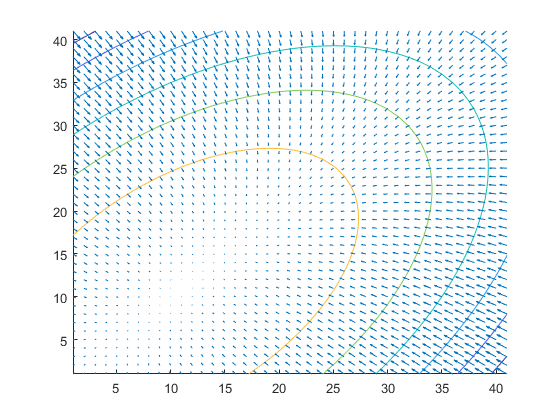

clf
hold on
[px, py] = gradient(f_grid, 0.1, 0.1);
contour(f_grid)
quiver(px, py)

clf
hold on
contourf(x_grid, y_grid, f_grid)
axis equal
r = [1 -1]

r =      1    -1


lambda = 0.1

lambda = 0.1000

delta = 1.5

delta = 1.5000

threshold = 0.1

threshold = 0.1000

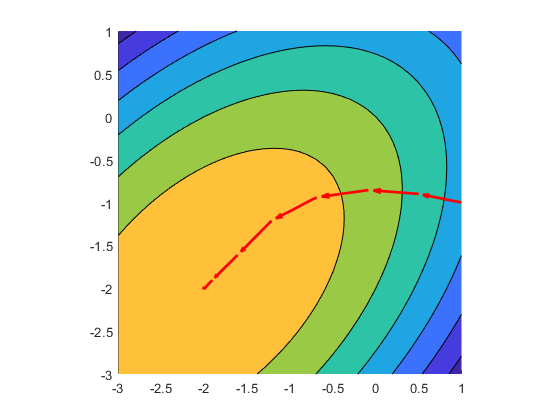

while 1
    r_grad = double(subs(grad, [x, y], [r(1), r(2)])) * lambda;
    quiver(r(1), r(2), r_grad(1), r_grad(2), 'r', 'LineWidth', 2, 'MaxHeadSize', 0.5)
    
    r = r + r_grad;
    %z = double(subs(f, [x, y], [r(1), r(2)]));
    lambda = lambda * delta;
    
    if norm(r_grad) < threshold
        break
    end
end